clear;
cfgm.backFillAum = false;
PubEqPath.addLibPath('_util','_data','_platform','_database','_file','_date');
if exist(pwd + "\EurekaHedge", 'dir') addpath(pwd + "\EurekaHedge"), end
if getenv('USERNAME')=="dpopov"
  inDataDir = fullfile(PubEqPath.localDataPath(), 'EH'); 
else  
  inDataDir = fullfile(PubEqPath.dataPath(), 'EH'); 
end
  
fnCache = "ehRollData_2019-1104_all";
load(fullfile(inDataDir, ensureFileExt(fnCache, "mat")));

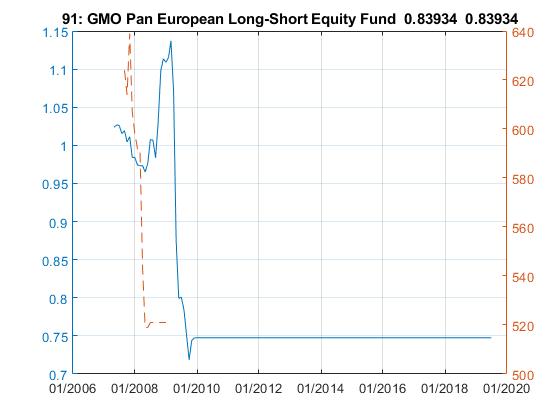

adjAum = dbData.aumTS;
for i = 2:size(dbData.equHFrtns.values, 1)
    adjAum(i:end,:) = round(adjAum(i:end,:) - dbData.aumTS(i-1,:) .* dbData.equHFrtns.values(i, :));
end % i
%    set(gcf,'Visible','on');
f = figure;
figure(f);

sz = size(dbData.equHFrtns.values);
for i = 1:sz(2)
    title(string(i) + ": " + dbData.equHFrtns.header(i) + "  " + string(aumClean2.pctUnexp(i))+ "  " + string(aumClean2.pctUnexpMod(i)));
    yyaxis left;
    plot(dbData.equHFrtns.dates, calcCum(dbData.equHFrtns.values(:,i), 1));
    yyaxis right;
    %plot(dbData.equHFrtns.dates, dbData.aumTS(:,i)./1000./1000);
    p=plot(dbData.equHFrtns.dates, [adjAum(:,i)./1000./1000 dbData.aumTS(:,i)./1000./1000]);
    datetick('x', 'mm/yyyy');
    grid; 
    tmp=1;
    delete(p);
end % for i

The section below is for funds that we are invested in or prospecting. Requires a run of rapcScript.m to a point right before a call to preProcRapcInput() (currently line 53).

k=9;
    yyaxis left
    plot(outStruct.equHFrtns.dates, calcCum(outStruct.equHFrtns.values(:,k), 1));
    yyaxis right
    plot(outStruct.equHFrtns.dates, outStruct.mktValue.values(:,k)./1000./1000);
    title(outStruct.equHFrtns.header(k));
    grid; 
    datetick('x', 'mm/yyyy');
    tmp=1;